% load pD1_B.mat
% load pD2_B.mat
% load pD3_B.mat
% load pD1_W.mat
% load pD2_W.mat
% load pD3_W.mat
% actual = zeros(20,1);
% measured = zeros(20,1);
% for n= 1:length(pD3_B)
%     actual(n,:)= mean([pD1_B(n,1),pD2_B(n,1),pD3_B(n,1),pD1_W(n,1),pD2_W(n,1),pD3_W(n,1)]);
%     measured(n,:) = mean([pD1_B(n,2),pD2_B(n,2),pD3_B(n,2),pD1_W(n,2),pD2_W(n,2),pD3_W(n,2)]);
% end
% plot(actual,measured,'-*')
% %linearization
% lin_V = 1./(measured+0.25);
% plot(actual,lin_V)

% [a_position, m_position] = linear_data(pD1_B,pD2_B,pD2_B,pD1_W,pD2_W,pD3_W,0.25)

clear all
% create arduino ref-objects
[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM10');

% Turn on board LED on and off to signal program has started
Blink(robotArduino, blinkLED,5);
disp('Data Collection Active');

Data Collection Active



% Configure test loop to collect n data points
nTests = input(['Enter number of range test positions, followed by enter: ']);
clc             % clear command window

% create a variable to hold eperimental position data
positionData = zeros(nTests,1);

r = rateControl(0.1);   % create a 0.1 hz loop rate
reset(r);                % reset loop time to zero

**Run robot control loop **(code that runs over and over)

controlFlag = 1;                % create a loop control
%tStart = tic;
while (controlFlag < nTests+1)  % loop till ntests data captured
    
    % collect data from robot sensors
    rangeData = SENSE(robotArduino, rawRangeIn);
    THINK();                % compute what robot should do next
    ACT();                  % command robot actuators

    % store experimental command versus actual data
    tic;
    positionData(controlFlag,1) = rangeData;
    Blink(robotArduino,blinkLED,1);
    waitfor(r)                  % wait for loop cycle to complete
    %T(controlFlag) = toc;
    controlFlag = controlFlag+1; % increment loop
end

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

Sense


ans = 0

%tEnd = toc(tStart)
%t_BTWN = sum(T)

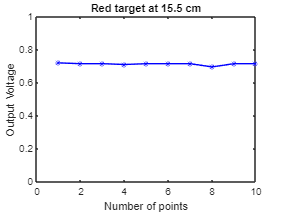

clear figure
plot(positionData,'b-*')
xlabel('Number of points')
ylabel('Output Voltage')
ylim([0 1])
title('Red target at 15.5 cm')


%time = [T(1) sum(T(1:2)) sum(T(1:3)) sum(T(1:4)) sum(T(1:5)) sum(T(1:6)) sum(T(1:7)) sum(T(1:8)) sum(T(1:9)) sum(T(1:10))]

%new_V = calibrate(positionData,0.25)
clear figure
% Plot and store commanded position data vs. actual position
%plot(time,positionData(:,1),'b-*');
% xlabel('Actual Position')
% ylabel('Measured Voltage')
% title('White Background - Data3')
%ylim([0 1])
% b = (1/nTests)*ones(1,nTests);
% a = 1;
% y = filter(b,a,new_V);
% hold on
% plot(time,y,'r')
% legend('Input Data','Filtered Data')
% hold off;

% pD3_W = positionData;
% save pD3_W
% 
% plot(pD3_W(:,1), pD3_W(:,2),'-*')
% xlabel('Actual Position')
% ylabel('Measured Voltage')
% title('White Background - Data3')
% grid

**Robot Functions** (store this codes local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. It requres which COM port your Arduino is attached to as its
% input and returns an Arduino object called robotArduino
% I. Munoz 2022 Rev A

% Create a global arduino object so that it  can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
robotArduino = arduino(COMPORT,'Uno','Libraries','Servo');

%configure pin 13 as a digital-out LED
blinkLED = 'D13';
configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure A0 pin as an analog input
rawRangeIn = 'A3';
configurePin(robotArduino,rawRangeIn,'AnalogInput')
end

function [] = Blink(a,LED, n)
% Blink toggles Arduino a LED on and off to indicate program running
% input n = # of blinks
% no output
% IMunoz 3/25/22

    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end
end

**Sense Function **(store all Sense related local functions here)

function rangeData = SENSE(robotArduino, rawRangeIn)
    disp('Sense');
    rangeData = readVoltage(robotArduino,rawRangeIn);
end
function calib_V = calibrate(data,c)
    calib_V = 1./(data+c);
end

function [actual, measured] = linear_data(data1,data2,data3,data4,data5,data6,k)
    actual = zeros(20,1);
    measured = zeros(20,1);
    for n= 1:length(data1)
        actual(n,:)= mean([data1(n,1),data2(n,1),data3(n,1),data4(n,1),data5(n,1),data6(n,1)]); %taking mean of all actual values
        measured(n,:) = mean([data1(n,2),data2(n,2),data3(n,2),data4(n,2),data5(n,2),data6(n,2)]); %taking mean of all sensed/measured values
    end
    tiledlayout(2,1)
    nexttile
    plot(actual,measured,'-*')
    xlabel('Actual Position')
    ylabel('Measured Voltage')
    title('Average Data')
    grid
    %linearization
    lin_V = 1./(measured+k);
    nexttile
    plot(actual,lin_V)
    xlabel('Actual Position')
    ylabel('Linearized Voltage')
    title('Linearization of Data')
    grid
end

**Think Functions **(store all Think related local functions here)

function THINK()
    % null function, not much thinking to do here
end

**Act Functions **(store all Act related local functions here)

function ACT()
    % nul function, not much acting to do here
end
